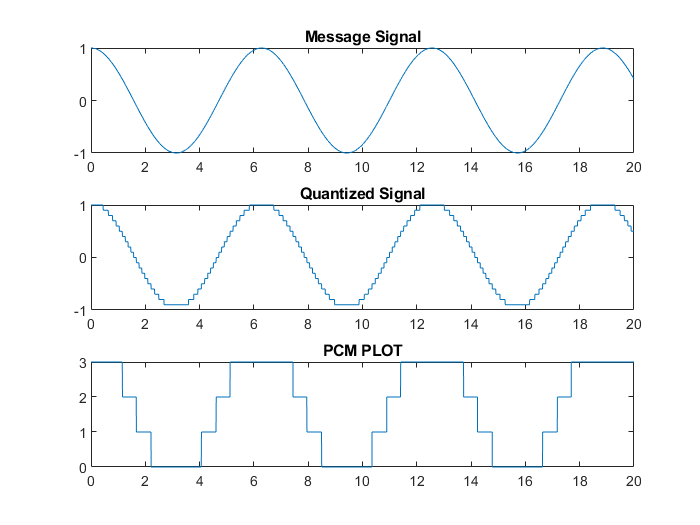

t = 0:0.0001:20; %sampling at niquist rate
c= 2; % bit depth of PCM coding
part = -1:0.1:1;%A quantization partition defines several contiguous, nonoverlapping ranges
%of values within the set of real numbers.
codebook = -1:0.1:1.1;%A codebook tells the quantizer which common value to assign to inputs that
%fall into each range of the partition.
msg = cos(t);
[~,quants] = quantiz(msg,part,codebook);%returns a vector that tells which interval each input is in
subplot(3,1,1);
plot(t,msg);
title('Message Signal');
subplot(3,1,2);
plot(t,quants);
title('Quantized Signal');
y = uencode(quants,c);
ybin=dec2bin(y,c); %converting it to final binary form to make it transmit ready
subplot(3,1,3);
plot(t,y);
title('PCM PLOT');